This live script is the first script of Dr Ioannis Tsirkas in his effort to learn MATLAB. It can conduct several calculations involving replication measurements.

Input is a table named **data** which contains:

1st column: **Budding timepoints**

2nd column: ***lacO***** array midpoints**

3rd column: ***tetO***** array midpoints**

4th column: **Anaphase timepoints**

5th column: **Experiment Duration**

All timepoints are in **minutes**

May the God be with you!

This section calculates several experimental values

%Name of strain and/or genotype:
Strain = "COD RAF";

%Maximum time allowed for cells to undergo Anaphase after tetO array
%replication
MaxAllowedtime = 45;

BudTimes=data(:,1);
LacMid=data(:,2);
TetMid=data(:,3);
Anaphase=data(:,4);
Duration=data(:,5);

BudAnaphase=Anaphase-BudTimes;
%Calculates the duration between the budding until Anaphase
RepliTimes=TetMid-LacMid;
%Calculates the replication time between the lacO and tetO midarrays
LateSAna=Anaphase-TetMid;
%Calculates the duration between the replication of the tetO until Anaphase
Duratet=Duration-TetMid;
%Calculates the duration between the replication of the tetO array until
%the end of the experiment

This section calculates the median budding-Anaphase duration, median replication time and the number of cells in each category

BudAnaphaseReal=BudAnaphase(BudAnaphase>0);
MediBudAnaphaseReal=median(BudAnaphaseReal);
num0=size(BudAnaphaseReal,1);

MediRepliTime=median(RepliTimes);
num=size(RepliTimes,1);

This section plots the single-cell replication time measurements

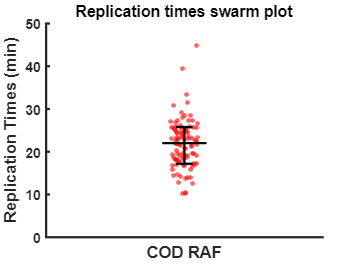

xRep=1;
qRep=quantile(RepliTimes,4);
minqRep=min(qRep);
maxqRep=max(qRep);
swarmchart(xRep,RepliTimes,10,"red",'filled','jitter','on','jitteramount',0.05,'MarkerFaceAlpha',0.6,'MarkerEdgeAlpha',0.6)
line([0.92,1.08],[MediRepliTime,MediRepliTime],Color='black',Linewidth=1.5)
line([1,1],[minqRep,maxqRep],Color='black',Linewidth=1.5)
line([0.97,1.03],[minqRep,minqRep],Color='black',Linewidth=1.5)
line([0.97,1.03],[maxqRep,maxqRep],Color='black',Linewidth=1.5)

ylim([0 50]);
title('Replication times swarm plot')
ylabel('Replication Times (min)',FontWeight="bold", FontSize=11)
xlabel(Strain,FontWeight="bold",FontSize=11)
set(gca,'xtick',[],LineWidth=1.5,Fontweight="bold")

This section calculates the median late S-Anaphase duration and the correlation between replication time and late S-Anaphase duration

Array1=[RepliTimes Duratet];
Array2=[LateSAna Duratet];
RepliTimesArray1=Array1(Duratet >= MaxAllowedtime);
LateSAnaArray2=Array2(Duratet >= MaxAllowedtime);
%The slide bar defines the remaining time which cells had to undergo
%Anaphase (until the end of the microscope experiment) after the
%replication of the tetO array. Both numbers should be the same!

Array3=[RepliTimesArray1 LateSAnaArray2];
RepliTimesCorr=Array3(LateSAnaArray2>0);
LateSAnaCorr=LateSAnaArray2(LateSAnaArray2>0);

num2=size(LateSAnaCorr, 1);
%Calculates the number of single cells that the late S-Anaphase duration
%was measured and used for the correlation with the replication

AnaPer=num2/size(Array3, 1);
%Calculates the percentage of cells which underwent Anaphase while having
%at least "MaxAllowedtimespan" min between the tetO replication and the end
%of the experiment

MedilateSAna=median(LateSAnaCorr);
%Calculates the median Late S-Anaphase duration of cells

[rho,pval]=corr(RepliTimesCorr,LateSAnaCorr);
%Calculates the Pearson correlation coefficient and the p value for the
%Replication Times and Late S-Anaphase duration comparison

This section plots the single-cell Late S-Anaphase duration measurements

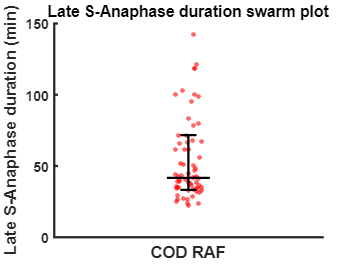

xAna=1;
qAna=quantile(LateSAnaCorr,4);
minqAna=min(qAna);
maxqAna=max(qAna);
swarmchart(xAna,LateSAnaCorr,10,"red",'filled','jitter','on','jitteramount',0.05,'MarkerFaceAlpha',0.6,'MarkerEdgeAlpha',0.6)
hold on
line([0.92,1.08],[MedilateSAna,MedilateSAna],Color='black',Linewidth=1.5)
line([1,1],[minqAna,maxqAna],Color='black',Linewidth=1.5)
line([0.97,1.03],[minqAna,minqAna],Color='black',Linewidth=1.5)
line([0.97,1.03],[maxqAna,maxqAna],Color='black',Linewidth=1.5)
hold off

ylim([0 150]);
title('Late S-Anaphase duration swarm plot')
ylabel('Late S-Anaphase duration (min)',FontWeight="bold", FontSize=11)
xlabel(Strain,FontWeight="bold",FontSize=11)
set(gca,'xtick',[],LineWidth=1.5,Fontweight="bold")

This section plots the Replication Times/Late S-Anaphase duration correlation graph

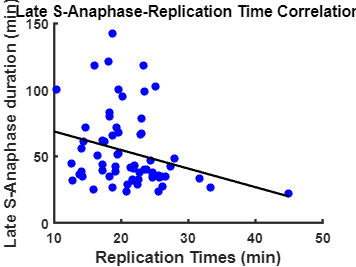

scatter(RepliTimesCorr,LateSAnaCorr, 30, 'filled', 'blue')
h1=lsline;
h1.Color='black';
h1.LineWidth=1.5;
ylim([0 150])
title('Late S-Anaphase-Replication Time Correlation')
ylabel('Late S-Anaphase duration (min)',FontWeight="bold", FontSize=11)
xlabel('Replication Times (min)',FontWeight="bold",FontSize=11)
set(gca,LineWidth=1.5,Fontweight="bold")

This section displays the results

disp("Here come the results for the " + Strain + " Strain")

Here come the results for the COD RAF Strain


disp(" ")

disp("The median Budding-Anaphase time of " + num0 + " cells is " + round(MediBudAnaphaseReal) + " min.")

The median Budding-Anaphase time of 49 cells is 76 min.


disp("The median Ρeplication time of " + num +  " cells is " + round(MediRepliTime) + " min.")

The median Ρeplication time of 97 cells is 22 min.


disp("The median Late S-Anaphase duration of " + num2 + " cells is " + round(MedilateSAna) + " min.")

The median Late S-Anaphase duration of 65 cells is 42 min.


disp("The fraction of cells which underwent Anaphase while having at least "+ MaxAllowedtime + " min after the tetO array replication until the end of the experiment is " + AnaPer + " (" + num2 + " out of " + size(Array3, 1) + " cells).")

The fraction of cells which underwent Anaphase while having at least 60 min after the tetO array replication until the end of the experiment is 0.68421 (65 out of 95 cells).


disp("The Pearson Coefficient R for Replication times and late S-Anaphase durations for " + num2 + " cells is " + rho + " and the p value is " + pval + ".")

The Pearson Coefficient R for Replication times and late S-Anaphase durations for 65 cells is -0.2733 and the p value is 0.02761.


disp(" ")

disp("<<...What I do not know I do not think I know either.>>")

<<...What I do not know I do not think I know either.>>


disp("                                            Sokrates")

                                            Sokrates
